clear all;
a = 1/sqrt(2);
b = 0.005;

%% 1

R1 = 1.2e3;
R2 = 1e3;
C = 0.1e-6;

f = linspace(0, 5e3, 10e3);
s = 2i .* pi .* f;

H = 2 ./ (s.^2 .* R1.^2 .* C.^2 + s .* R1 .* C + 1);

mag = abs(H);
phase = rad2deg(angle(H));

[peak, i_0] = max(mag);
i_c = find(mag < peak * (a + b) & mag > peak * (a - b));

f(i_0)

ans = 937.5938

f(i_c(1))

ans = 1.5437e+03

f(i_c(end))

ans = 1.5567e+03

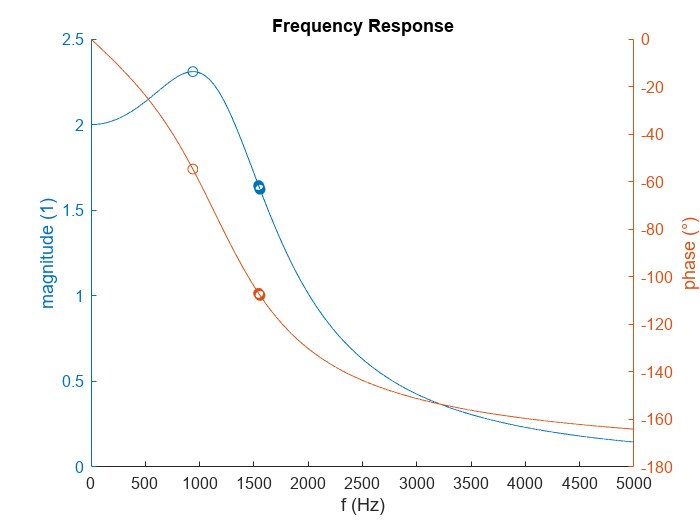

response(f, mag, phase, i_0, i_c);

%% 2

R1 = 560;
R2 = 560;
R3 = 270;
Ra = 2.2e3;
Rb = 1e3;
C1 = 0.47e-6;
C2 = 0.47e-6;
C3 = 1e-6;

f = linspace(0, 5e3, 1e3);
s = 2i .* pi .* f;

K = 1 + Rb ./ Ra;
K1 = (R1 .* R2 .* C1 .* C2).^-1;
K2 = (1 - K) ./ (R3 .* C1);
K3 = (C1.^-1 + C2.^-1) ./ R2;

H = K .* (s.^2 + K1) ./ (s.^2 + s .* (K2 + K3) + K1);

mag = abs(H);
phase = rad2deg(angle(H));

[peak, i_0] = max(mag);
i_c = find(mag < peak * (a + b) & mag > peak * (a - b));
[peak, i_0] = min(mag);

f(i_0)

ans = 605.6056

f(i_c(1))

ans = 365.3654

f(i_c(end))

ans = 1.0060e+03

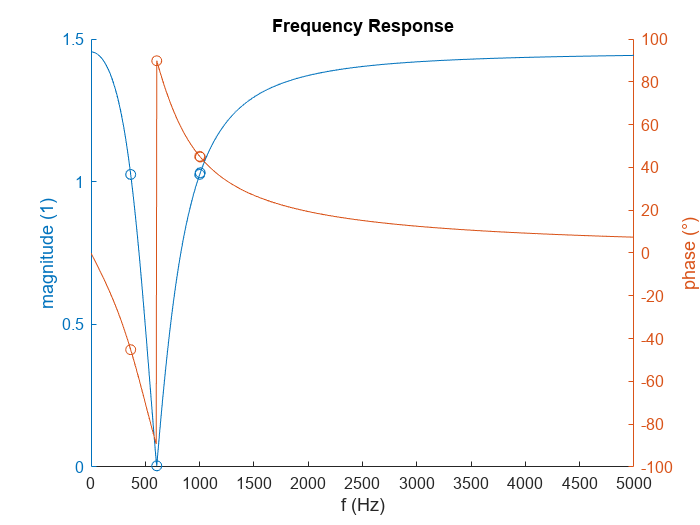


response(f, mag, phase, i_0, i_c);

%% 3

R1 = 1e3;
R2 = 2.2e3;
R3 = 10e3;
R4 = 6.8e3;
C = 4.7e-9;

f = linspace(0, 100e3, 1e3);
s = 2i .* pi .* f;

K1 = s.^2 .* R2 .* C.^2 + 2 .* s .* C;
K2 = s .* R2 .* C + 2;

H = (R2 .* (R3 + R4) .* K1) ./ (R2 .* R4 .* K1 - R3 .* K2 .* (R1 .* K1 + 1));

mag = abs(H);
phase = rad2deg(angle(H));

[peak, i_0] = max(mag);
i_c = find(mag < peak * (a + b) & mag > peak * (a - b));

f(i_0)

ans = 2.2832e+04

f(i_c(1))

ans = 1.9242e+04

f(i_c(end))

ans = 2.7093e+04

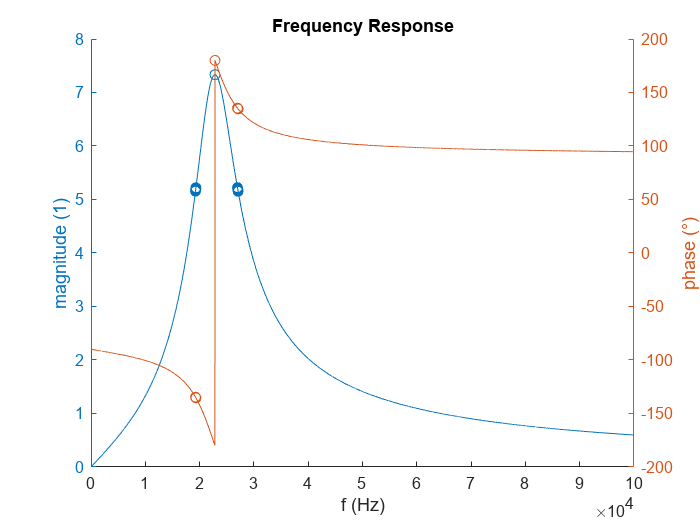

response(f, mag, phase, i_0, i_c);

%% 4

R1 = 1e3;
R2 = 2.2e3;
C = 4.7e-9;

f = linspace(0, 100e3, 1e3);
s = 2i .* pi .* f;

K1 = s.^2 .* R2 .* C.^2 + 2 .* s .* C;
K2 = s .* R2 .* C + 2;
H = -R2 .* K1 ./ (K2 .* (R1 .* K1 + 1));

mag = abs(H);
phase = rad2deg(angle(H));

[peak, i_0] = max(mag);
i_c = find(mag < peak * (a + b) & mag > peak * (a - b));

f(i_0)

ans = 2.2823e+04

f(i_c(1))

ans = 1.2112e+04

f(i_c(end))

ans = 4.3243e+04

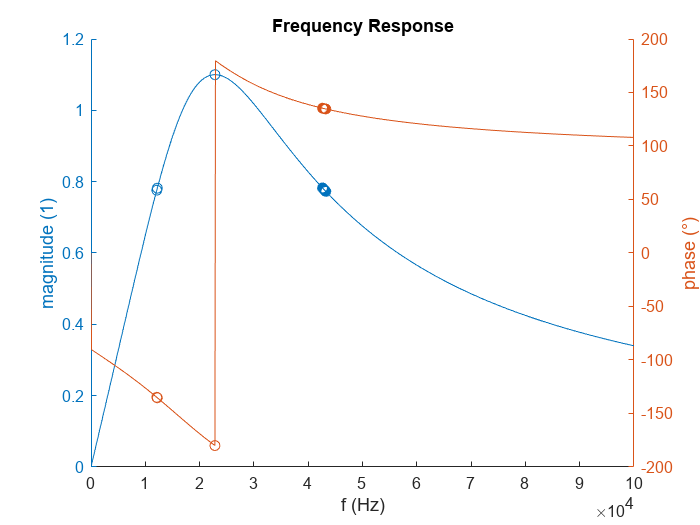

response(f, mag, phase, i_0, i_c);

R1 = 1e3;
R2 = 2.2e3;
R3 = 10e6;
R4 = 1;
C = 4.7e-9;

f = linspace(0, 100e3, 100e3);
s = 2i .* pi .* f;

K1 = s.^2 .* R2 .* C.^2 + 2 .* s .* C;
K2 = s .* R2 .* C + 2;

H1 = (R3 + R4) ./ R4;
H2 = 1 + (1 - (R3 + R4) ./ R4) .* (R1 + 1 ./ K1) ./ (R2 ./ K2);
H = H1 ./ H2;

mag = abs(H);
phase = rad2deg(angle(H));

[peak, i_0] = max(mag);
i_c = find(mag < peak * (a + b) & mag > peak * (a - b));

f(i_0)

ans = 2.2830e+04

f(i_c(1))

ans = 1.2047e+04

f(i_c(end))

ans = 4.3267e+04

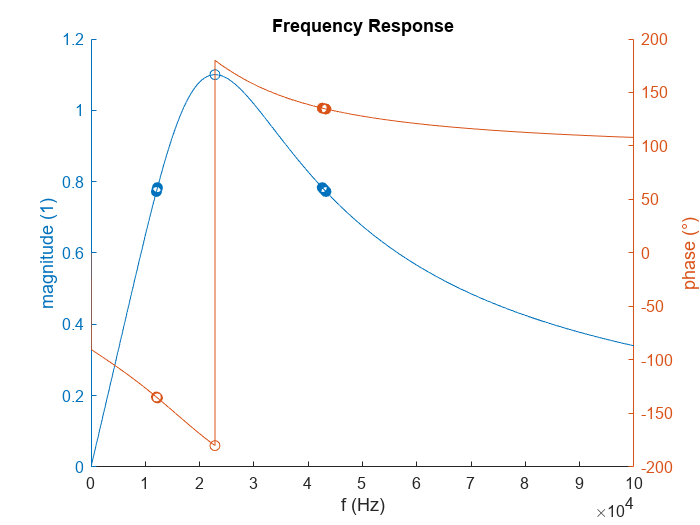

response(f, mag, phase, i_0, i_c);

function [] = response(f, mag, phase, i_0, i_c)
    figure;

    yyaxis left;
    hold on;
    plot(f, mag);
    plot(f(i_0), mag(i_0), "o");
    plot(f(i_c), mag(i_c), "o");
    ylabel("magnitude (1)");
    
    yyaxis right;
    hold on;
    plot(f, phase);
    plot(f(i_0), phase(i_0), "o");
    plot(f(i_c), phase(i_c), "o");
    ylabel("phase (°)");
    
    xlabel("f (Hz)");
    title("Frequency Response");
    print('-clipboard', '-dbitmap');
end